TrendTradingMainScript

Preparation

clear
    
tic

Read data

load TrendTrading.mat % IndexTT PriceTTFullRaw VolumeTTFullRaw
% IndexTT ;
% PriceTTFullRaw ;
% VolumesTTFullRaw = VolumeTTFullRaw ;

Clean data

PricesTTFull = fillmissing (PricesTTFullRaw, "previous") ;
PricesTTFull = fillmissing (PricesTTFull, "next") ;

VolumesTTFullRawVars = VolumesTTFullRaw.Variables ;
VolumesTTFullRawVarsIdx = VolumesTTFullRawVars < 100';
VolumesTTFullRawVars (VolumesTTFullRawVarsIdx) = NaN ;
VolumesTTFullRaw.Variables = VolumesTTFullRawVars ;
VolumesTTFull = fillmissing (VolumesTTFullRaw, "previous") ;


Split dataset into IST and OST

nRowFull = int64 (size (PricesTTFull,1)) ;
nRowISTproportion = 80/100 ;  % Proportion of dataset to be in Sample Dataset
nRowIST = int64(round(nRowISTproportion*nRowFull)) ;
nRowOST = round (nRowFull-nRowIST) ;

% IST dataset
PricesIST = (PricesTTFull (1:nRowIST, :)) ;
VolumesIST = (VolumesTTFull (1:nRowIST, :)) ;

% OST dataset
PricesOST = (PricesTTFull (nRowIST:end, :)) ;
VolumesOST = (VolumesTTFull (nRowIST:end, :)) ;


Backtest

% Backtest input

x = [10^3	10^6 -50  1	1	25 -8]

x =         1000     1000000         -50           1           1          25          -8


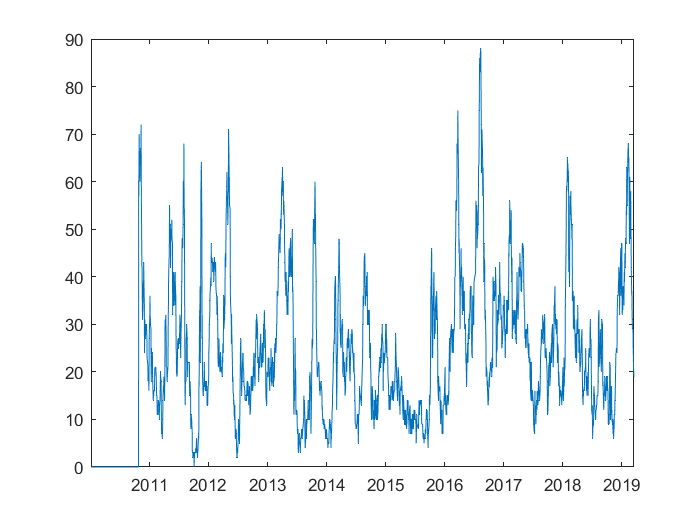

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn               6.1224     
    SharpeRatio             0.077597     
    Volatility              0.013267     
    AverageTurnover           0.1072     
    MaxTurnover              0.86364     
    AverageReturn          0.0010293     
    MaxDrawdown              0.38512     
    AverageBuyCost            53.023     
    AverageSellCost           70.603     


EndCumSumVar = -7.1224

TradingPeriod = 8.3973

CAGR = -0.2634

SharpeRatio = -1.2269

Sortino = -1.7910

Elapsed time is 19.686017 seconds.


SharpeRatio = -1.2269

% x = [10^3	10^9	100	80	200	10^15	10^15	200	80	200	200	80	200]

% lb = [1	1 -50  1	1	-50 -50] ;
% ub = [10^15 10^15	80 10^15 10^15 80 80 ] ;

% LowSkipValTreshCorrection = x(1) ;
% MinValue = x(2) ;
% MomContRetTrheshold = x(3) ; 
% LowLiquidThreshold = x(4) ;
% LiquidSurgThreshold = x(5) ;
% MomMainRetThreshold = x(6) ;
% StopLossThreshold = x(7) ;

% Call the function
SharpeRatio = TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) 

Optimize parameters in IST

options = optimoptions ('ga', 'UseParallel', true, 'UseVectorized', ...
    false, "FunctionTolerance", 0.05, "MaxGenerations",20, 'MaxTime', 60*5)

options =   ga options:

   Set properties:
               FunctionTolerance: 0.05
                  MaxGenerations: 20.00
                         MaxTime: 300.00
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 0.00
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.80
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50.00
                    MaxStallTime: Inf
                     MutationFcn: {@mutationgaus

options = optimoptions(options,'PlotFcn',{@gaplotbestf,@gaplotstopping})

options =   ga options:

   Set properties:
               FunctionTolerance: 0.05
                  MaxGenerations: 20.00
                         MaxTime: 300.00
                         PlotFcn: {@gaplotbestf  @gaplotstopping}
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 0.00
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.80
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50.00
                    


FitnessFunction = @(x) TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) ;
nvars = 7 ;
lb = [1	1 -50  1	1	-50 -50] ;
ub = [10^15 10^15	80 10^15 10^15 80 80 ]

% ConstraintFunction = @nlconGA ;
IntCon = 1:nvars ;

[x, fval] = ga(FitnessFunction, nvars, [], [], [], [], lb, ub, [],IntCon, options )


summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar =

    -1


TradingPeriod =

    8.3973


CAGR =

     0


SharpeRatio =

     0

Elapsed time is 28.664355 seconds.

summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxD


summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar =

    -1


TradingPeriod =

    8.3973


CAGR =

     0


SharpeRatio =

     0


Sortino =

   NaN

Elapsed time is 29.127437 seconds.

summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn             


xSharpeGAOptimized = x ;


Optimize Sharpe Ratio by using surrogateopt

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


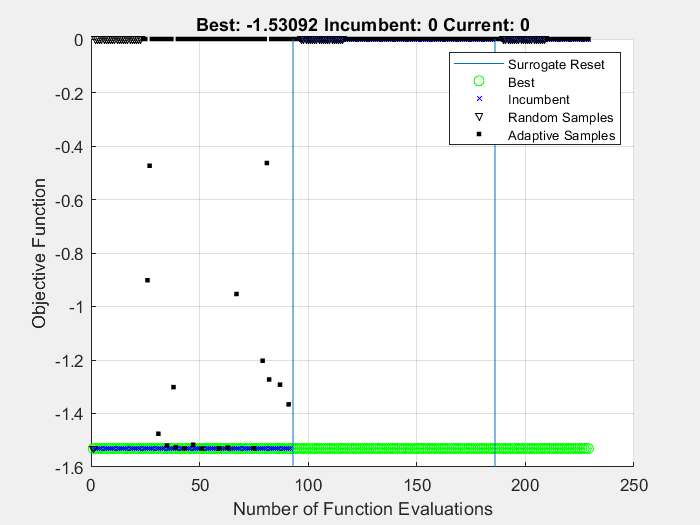

Optimization stopped by a plot function or output function.


%surrogateopt for expensive optim problems

options = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot", ...
    "ConstraintTolerance",1e-2,'UseParallel', true, 'MaxFunctionEvaluations',100);

fun = @(x) TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) ;
nvars = 7 ;
lb = [1	1 -50  1	1	-50 -50] ;
ub = [10^15 10^15	80 10^15 10^15 80 80 ] ;
intcon = 1:nvars ;

[xSharpeSur,fvalm,~,~,pop] = surrogateopt(fun,lb,ub,intcon,options);


xSharpeSurOptimized = xSharpeSur ;


Optimize Sortino Ratio by using surrogateopt

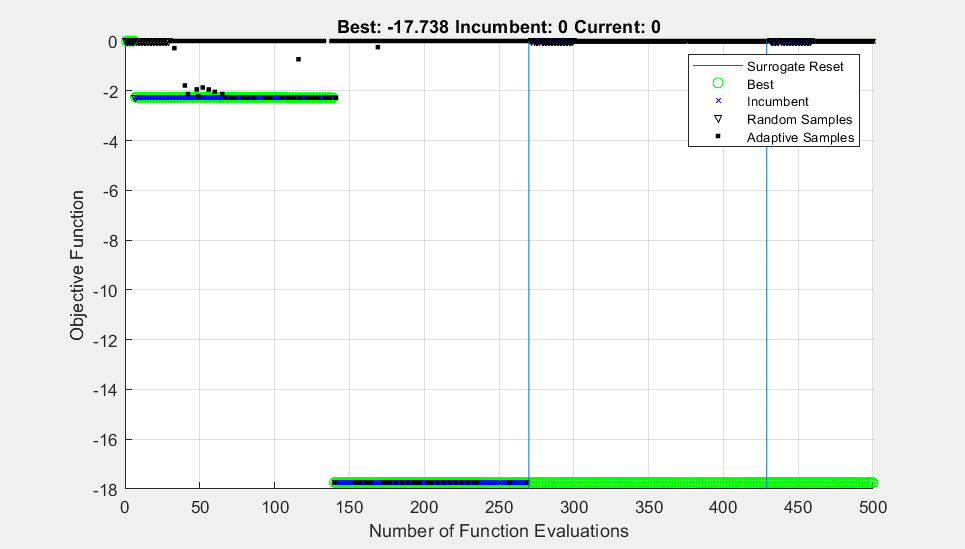

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


%surrogateopt for expensive optim problems

options = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot", ...
    "ConstraintTolerance",1e-3,'MaxFunctionEvaluations',200, 'UseParallel', true);

fun = @(x) TrendTradingFcnMultiVarSortino (x, PricesIST, VolumesIST) ;
nvars = 13 ;
lb = [1	1	1	-50	1	1	1	1	-50	1	1	-50	1] ;
ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	100] ;
intcon = 1:nvars ;

[xSortinoSur,fvalm,~,~,pop] = surrogateopt(fun,lb,ub,intcon,options);

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SharpeRatio = 0

Sortino = NaN

Elapsed time is 12.336697 seconds.


summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SortinoRatio = 0

Elapsed time is 12.500830 seconds.


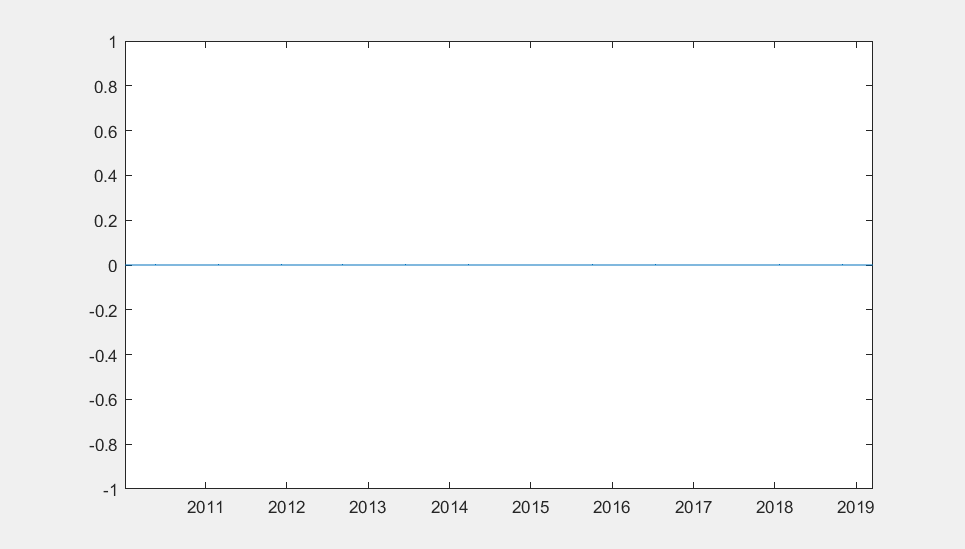

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SharpeRatio = NaN

SortinoRatio = NaN

Elapsed time is 13.045303 seconds.


Unrecognized function or variable 'isna'.

Error in SharpeSortinoCAGRFitFcn (line 6)
SharpeRatio (isna (SharpeRatio)) = 0 ;

Error in TrendTradingMainScript (line 102)
fun = @(x) SharpeSortinoCAGRFitFcn (x, PricesIST, VolumesIST) ;

Error in 

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SharpeRatio = 0

Sortino = NaN

Elapsed time is 25.856827 seconds.


summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SortinoRatio = 0

Elapsed time is 26.548901 seconds.


summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SharpeRatio = NaN

SortinoRatio = NaN

Elapsed time is 26.798486 seconds.



xSortinoSurOptimized = xSortinoSur 

Apply the parameters into IST - OST

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                2.5706    
    SharpeRatio              0.096824    
    Volatility               0.006523    
    AverageTurnover         0.0094374    
    MaxTurnover                   0.5    
    AverageReturn          0.00063143    
    MaxDrawdown               0.19051    
    AverageBuyCost             3.0747    
    AverageSellCost            4.0038    


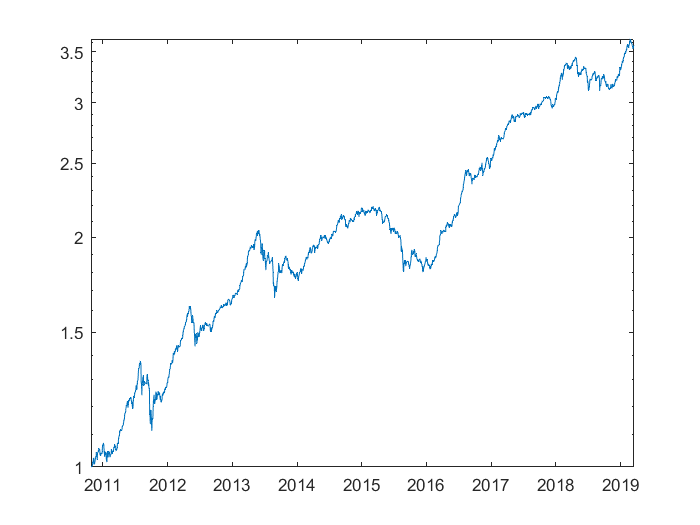

EndCumSumVar = -3.5706

TradingPeriod = 8.3973

CAGR = -0.1637

SharpeRatio = -1.5309

Sortino = -2.0473

Elapsed time is 20.871000 seconds.


SharpeRatioOptimized = -1.5309

% xOptimized = xGAOptimized;
xOptimized = xSharpeSurOptimized ;
% xOptimized =  xSortinoSurOptimized ;

SharpeRatioOptimized = TrendTradingFcnMultiVarSharpeGraph (xOptimized, PricesIST, VolumesIST) 

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                0.2652    
    SharpeRatio               0.07503    
    Volatility              0.0089545    
    AverageTurnover           0.01402    
    MaxTurnover                   0.5    
    AverageReturn          0.00067096    
    MaxDrawdown                0.2924    
    AverageBuyCost             2.2077    
    AverageSellCost            2.4075    


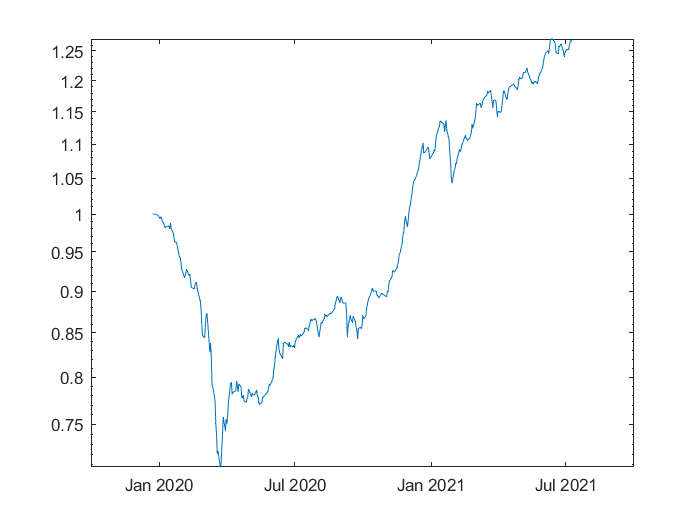

EndCumSumVar = -1.2652

TradingPeriod = 1.5410

CAGR = -0.1649

SharpeRatio = -1.1863

Sortino = -1.6475

Elapsed time is 4.465569 seconds.


SharpeRatioOptimized = -1.1863

SharpeRatioOptimized = TrendTradingFcnMultiVarSharpeGraph (xOptimized, PricesOST, VolumesOST)

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                3.3422    
    SharpeRatio              0.084812    
    Volatility              0.0067873    
    AverageTurnover         0.0099602    
    MaxTurnover                   0.5    
    AverageReturn          0.00057553    
    MaxDrawdown               0.33636    
    AverageBuyCost             3.6863    
    AverageSellCost            4.8398    


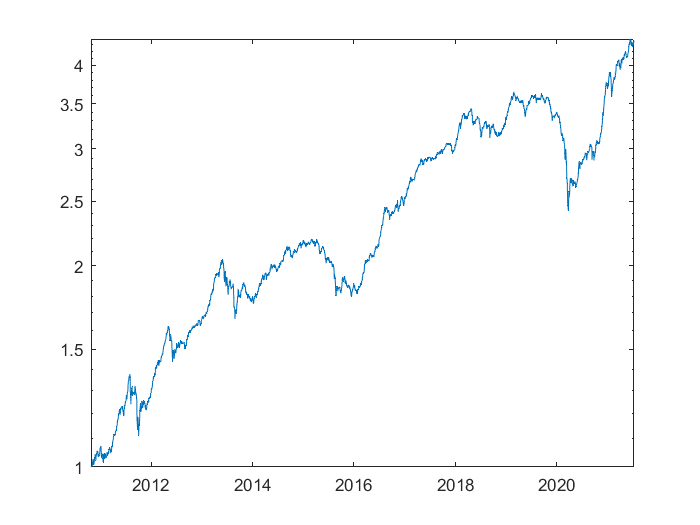

EndCumSumVar = -4.3422

TradingPeriod = 10.7096

CAGR = -0.1470

SharpeRatio = -1.3410

Sortino = -1.8113

Elapsed time is 28.910209 seconds.


SharpeRatioOptimized = -1.3410

SharpeRatioOptimized = TrendTradingFcnMultiVarSharpeGraph (xOptimized, PricesTTFull, VolumesTTFull)

Examine OST

Save Variable

% PricesTTFullRaw = PricesTTFull ;
% VolumesTTFullRaw = VolumesTTFull ;

save ("TrendTrading.mat", 'PricesTTFullRaw', "VolumesTTFullRaw",  "xSharpeSurOptimized", 'xSortinoSurOptimized', 'xOptimized')

Closing

toc

Elapsed time is 1942.416299 seconds.
